# **Task 1 **Path Finding Doc

map = load("multilayerMap.mat").map; % Data Loading

### **Binary Road Map**

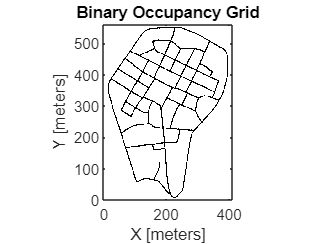

binaryMap = map(:,:,1);     % Binary Road Map
figure
show(binaryOccupancyMap(binaryMap))

### **Speed Limit Cost Map**

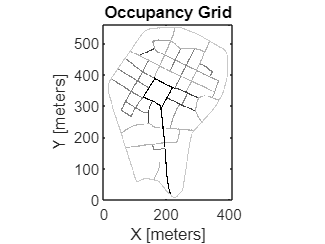

speedMap = map(:,:,2);                              % Speed Limit Cost Map
costMap_normalized = speedMap./max(max(speedMap));  % Normalization to value 0-1
speedOccMap = occupancyMap(costMap_normalized);     % Creating occupancyMap object

show(speedOccMap)

### **Traffic Intensity Cost Map**

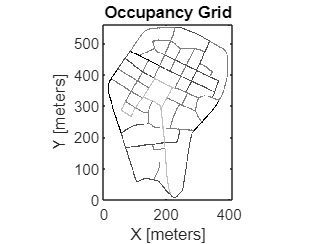

trafficMap = map(:,:,3);                                    % Traffic Intensity Map
trafficMap_normalized = trafficMap./max(max(trafficMap));   % Normalization to value 0-1
trafficOccMap = occupancyMap(trafficMap_normalized);        % Creating occupancyMap object

show(trafficOccMap)

### Obstacle Cost Map

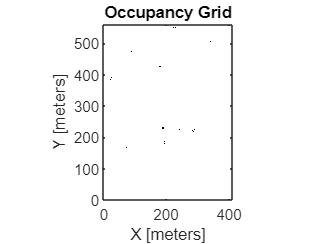

obstacleMap = map(:,:,4);                                       % Obstacle Cost Map
obstacleMap_normalized = obstacleMap./max(max(obstacleMap));    % Normalization to value 0-1
obstacleOccMap = occupancyMap(obstacleMap_normalized);          % Creating occupancyMap object

show(obstacleOccMap)

### Full Cost Map

Calculation based on equasion:


$$cost=speedLimitCost∙trafficIntensity+obstacleCost$$


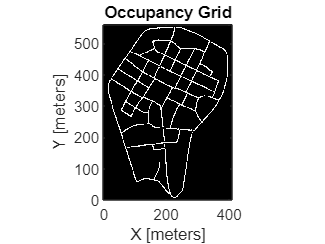

costMap = speedMap .* trafficMap + obstacleMap;     % Based on doc equation
costMap_normalized = costMap./max(max(costMap));    % Normalization to 0-1 value

costMap_normalized = costMap_normalized*0.98;       % Rescaling cost map
costMap_normalized(costMap_normalized==0) = 1;      % Setting up everything that is not road as an obstacle (cost = 1)
occCostMap = occupancyMap(costMap_normalized);      % Creating occupancyMap object based on costMap
occCostMap.OccupiedThreshold = 0.99;                % Setting occupancyMap parameters
occCostMap.FreeThreshold = 0.001;

show(occCostMap)

### Planner A*

It was decided to use planner A*, which is characterised by high path-finding speed. Unfortunately, not all solutions determined by it are optimal. In real cases, which are usually much more important, it is the speed of operation that matters, even if the solution is almost optimal.

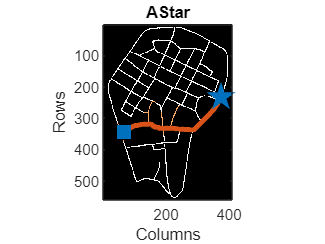

[startPoint, stopPoint] = startStopGenerator(binaryMap);    % Start and stop points calculations
planner = plannerAStarGrid(occCostMap);                     % Creating A* planner object
path = plan(planner,startPoint,stopPoint);                  % Path calculation
show(planner)